# **Scar Tissue Detection in Lung CT Scans**

Authors: Matthew Nguyen, Michael Guyot, Cameron Manson, Nathan Jones

Course: BME 3053C Computer Applications for BME

Term: Fall 2021

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

Note: change 'image_folder" to directory of cropped image

clc; clear;
breakOutLoop = true; % used for terminating script
n = 0;
image_folder = '/Users/mattn/OneDrive - University of Florida/01 BME/BME3053/Group Project/cropped_Images_USE';

Determine the total number of images in the file and obtain each image from the file

fileNames = dir(fullfile(image_folder,'*jpg'));
total_num_images = numel(fileNames);

while n <= total_num_images && breakOutLoop
    
    clf;
    advSegment = false; % used in scarDetectionAnalysis() for lung boundaries
    keepGoing = true; % used to determine if futher segmentation is needed
    n = n+1; % counter for number of images
    check = '';

    
    %gets image directory from struct
    name = fullfile(image_folder, fileNames(n).name);
    names(n) = {fileNames(n).name};    

Convert image to grey scale

    while keepGoing
        delete('var.mat') % resets 'global' variables
        I = im2gray(im2double(imread(name)));

Perform edge detection in the lungs and fill in the surface area

        binaryImage = edgeDetectLung(I);
        binaryImage = imfill(binaryImage, 'holes');
        binaryImage = imclearborder(binaryImage,4);

Take only the two largests blobs, which represent the lungs

        lungBinaryIm = lungBlobDetection(binaryImage);

Mask the pixel index index of the lungs to the original image

        lungIm = I;
        lungIm(lungBinaryIm == 0) = 0;

Identify scar tissue and overlay it with the original image

        binary_filt = scarIdentify(lungIm);
        save('var.mat'); %creates global variables
        run('TestGUI.m');
        waitfor(TestGUI)

Evaluate scar tissue detection effectiveness

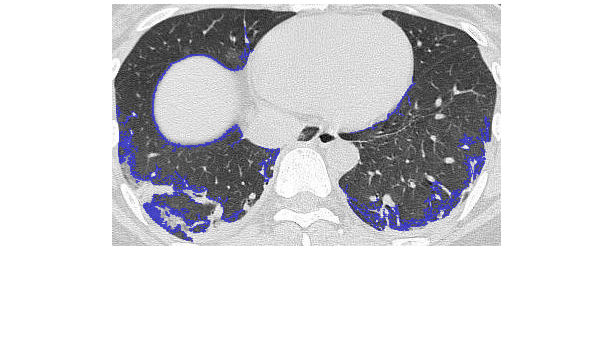

        [name, keepGoing, breakOutLoop, advSegment] = scarDetectionAnalysis(I, name, n, keepGoing, breakOutLoop, advSegment);
    end
end

Delete new image from the folder

delete('new.jpg');